# `Data Generation Code`

#### `Load Files`

% Housekeeping
clc;
clear;
close all;

% Load State Space Model
load('linsys1.mat');
load_system('LQR.slx');

# `Rearrange Matrix `

`Matrix A`

% Define desired column order

col_order = [1, 3, 5, 8, 2, 4, 6, 7, 9];

% Define desired row order
row_order = [1, 3, 5, 8, 2, 4, 6, 7, 9];

% Original matrices
AB_Ori = linsys1.A;

% Rearrange matrices
AB = AB_Ori(row_order, col_order);    % Rearranges Matrix

% Display rearranged matrices
disp('Matrix A2 Rearranged:');

Matrix A2 Rearranged:


disp(AB);

   -0.0239    0.0015   13.6309   -9.7928   -0.0004         0    4.0598         0         0
   -0.1096   -0.4226  229.8670    0.5804   -0.0015   -4.0598         0   -0.3039         0
   -0.0019   -0.0200   -0.6745         0   -0.0000         0         0         0         0
         0         0    0.9995         0         0         0   -0.0310         0         0
   -0.0007    0.0000         0    0.0180   -0.1102  -13.7311 -231.5577    9.7881         0
    0.0003   -0.0000         0         0   -0.0174   -0.8215    0.3566         0         0
   -0.0001   -0.0003         0         0    0.0060    0.0338   -0.3377         0         0
         0         0   -0.0018         0         0    1.0000   -0.0593         0         0
         0         0    0.0311         0         0         0    1.0013         0         0



`Matrix B`

% Original matrices
BB_Ori = linsys1.B;

% Rearrange matrices
BB  = BB_Ori(row_order, :);   % Rearranges Matrix

% Display rearranged matrices
disp('Matrix B1 Rearranged:');

Matrix B1 Rearranged:


disp(BB);

         0   -0.7215         0    9.8100    9.8100
         0  -12.1666         0         0         0
         0   -4.8534         0    0.3924    0.3924
         0         0         0         0         0
         0         0    3.8333         0         0
   -1.5802         0    0.6064    0.0407   -0.0407
   -0.0331         0   -0.6798    0.7804   -0.7804
         0         0         0         0         0
         0         0         0         0         0



#### `Rearranged State Space System`

D = linsys1.D;
syys = ss(AB,BB,eye(9),D)

syys =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1    -0.02393    0.001493       13.63      -9.793  -0.0004195           0        4.06           0           0
   x2     -0.1096     -0.4226       229.9      0.5804   -0.001477       -4.06           0     -0.3039           0
   x3   -0.001949    -0.02005     -0.6745           0  -1.328e-05           0           0           0           0
   x4           0           0      0.9995           0           0           0    -0.03103           0           0
   x5  -0.0006908   4.096e-05           0     0.01802     -0.1102      -13.73      -231.6       9.788           0
   x6   0.0003026  -3.386e-05           0           0    -0.01737     -0.8215      0.3566           0           0
   x7   -0.000123  -0.0002976           0           0    0.006012     0.03382     -0.3377           0           0
   x8           0           0    -0.00184           0           0       

# `Augmented K`

#### `Linear Quadratic Regulator (LQR)`

t1 = [0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0];
t2 = [0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0];
t3 = [0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0];

C  = [1 0 0 0 0 0 0 0 0;
     0 -1 0 1 0 0 0 0 0; 
     0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 1 0;
     0 0 0 0 0 0 0 0 1];

A_aug = [syys.A t1;
          -C t3];
B_aug = [syys.B;t2];

Q_aug = [1 0 0 0 0 0 0 0 0 0 0 0 0 0;
        0 1 0 0 0 0 0 0 0 0 0 0 0 0;
        0 0 1 0 0 0 0 0 0 0 0 0 0 0;
        0 0 0 1 0 0 0 0 0 0 0 0 0 0;
        0 0 0 0 1 0 0 0 0 0 0 0 0 0;
        0 0 0 0 0 1 0 0 0 0 0 0 0 0; 
        0 0 0 0 0 0 1 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 1 0 0 0 0 0 0;   
        0 0 0 0 0 0 0 0 1 0 0 0 0 0;
        0 0 0 0 0 0 0 0 0 100 0 0 0 0;
        0 0 0 0 0 0 0 0 0 0 100 0 0 0;
        0 0 0 0 0 0 0 0 0 0 0 100 0 0;
        0 0 0 0 0 0 0 0 0 0 0 0 100 0
        0 0 0 0 0 0 0 0 0 0 0 0 0 100];

R_aug = [10 0 0 0 0;
        0 100 0 0 0;
        0 0 10000 0 0;
        0 0	0 10000 0;
        0 0 0 0 10000];

K_aug   = lqr(A_aug,B_aug,Q_aug,R_aug)

K_aug =     0.1090    1.3198   -3.1695 -304.1244    1.0835   -3.9638  -45.3116    3.7593  -29.9849   -0.0871    0.5368   -2.8388    0.2526    1.2576
    0.3460    2.9901  -11.8982 -743.4267    0.0125    0.0502   -0.1211   13.0652  -21.7676   -0.3164    0.1979   -0.0164   -0.9266    0.0428
    0.0127    0.1234   -0.3116  -28.8228    0.0233    0.0028   -1.1191    0.8062    1.7375   -0.0132    0.0460   -0.0266    0.0110   -0.0829
    0.0932    0.0849   -0.2239  -20.9216   -0.0102   -0.0030    1.2202    0.2173   -0.5055   -0.0806    0.0313    0.0236    0.0350    0.0273
    0.0632   -0.2077    0.5137   47.2263    0.0128    0.0030   -1.2137   -0.6801    1.2811   -0.0483   -0.0789   -0.0259   -0.0012   -0.0279


Kp      = K_aug(1:5,1:9)

Kp =     0.1090    1.3198   -3.1695 -304.1244    1.0835   -3.9638  -45.3116    3.7593  -29.9849
    0.3460    2.9901  -11.8982 -743.4267    0.0125    0.0502   -0.1211   13.0652  -21.7676
    0.0127    0.1234   -0.3116  -28.8228    0.0233    0.0028   -1.1191    0.8062    1.7375
    0.0932    0.0849   -0.2239  -20.9216   -0.0102   -0.0030    1.2202    0.2173   -0.5055
    0.0632   -0.2077    0.5137   47.2263    0.0128    0.0030   -1.2137   -0.6801    1.2811


Ki      = K_aug(1:5,10:14)

Ki =    -0.0871    0.5368   -2.8388    0.2526    1.2576
   -0.3164    0.1979   -0.0164   -0.9266    0.0428
   -0.0132    0.0460   -0.0266    0.0110   -0.0829
   -0.0806    0.0313    0.0236    0.0350    0.0273
   -0.0483   -0.0789   -0.0259   -0.0012   -0.0279


Acl     = A_aug-(B_aug*K_aug)

Acl = 1.0e+03 *

   -0.0013    0.0034    0.0022   -0.8042   -0.0000    0.0000    0.0039    0.0140   -0.0233    0.0010    0.0006    0.0000   -0.0010    0.0000
    0.0041    0.0360    0.0851   -9.0444    0.0002   -0.0034   -0.0015    0.1587   -0.2648   -0.0038    0.0024   -0.0002   -0.0113    0.0005
    0.0016    0.0145   -0.0585   -3.6185    0.0001    0.0002   -0.0006    0.0636   -0.1060   -0.0015    0.0010   -0.0001   -0.0045    0.0002
         0         0    0.0010         0         0         0   -0.0000         0         0         0         0         0         0         0
   -0.0000   -0.0005    0.0012    0.1105   -0.0002   -0.0137   -0.2273    0.0067   -0.0067    0.0001   -0.0002    0.0001   -0.0000    0.0003
    0.0002    0.0020   -0.0048   -0.4603    0.0017   -0.0071   -0.0707    0.0054   -0.0484   -0.0001    0.0008   -0.0045    0.0004    0.0020
   -0.0000   -0.0001    0.0003    0.0235    0.0001   -0.0001   -0.0045   -0.0000    0.0016    0.0000   -0.0000   -0.0002   -0.0000   -0.0

St      = eig(Acl)

St =   -6.9484 + 9.2948i
  -6.9484 - 9.2948i
  -8.3257 + 0.0000i
  -2.4308 + 4.0473i
  -2.4308 - 4.0473i
  -4.3793 + 0.0000i
  -1.2361 + 0.0000i
  -0.6163 + 0.9371i
  -0.6163 - 0.9371i
  -0.8340 + 0.8302i


# `Simulink`

% Define simulation parameters
simtime     = 10000;  % Total simulation time in seconds
numsamples  = 100000; % Total number of samples
step        = 100;    % Step duration

% Calculate the sample time and create the time vector
sampletime  = simtime / numsamples;           % Sample time for each step
t           = (0:numsamples-1) * sampletime;  % Time vector

% Step input signals
u = zeros(numsamples, 5);

% Step inputs for u-velocity
u(t >= 0.5*step, 1)      = -0.5;
u(t >= 1*step, 1)   = 0.5;      
u(t >= 15*step, 1)   = 0;

% Inputs for Gamma
u(t >= 20*step, 2) = 0.1750;
u(t >= 45*step, 2) = 0.1163;
u(t >= 65*step, 2) = 0.0582;
u(t >= 85*step, 2) = 0;

% Inputs for Beta
u(t >= 45*step, 3) = -0.053;
u(t >= 50*step, 3) = 0.053;
u(t >= 55*step, 3) = 0;

% Step inputs for Phi
u(t >= 60*step, 4)  = -0.0873;
u(t >= 65*step, 4)  = 0.0873;    
u(t >= 70*step, 4)  = 0;    

% Step inputs for Psi
u(t >= 75*step, 5)  = -0.053;
u(t >= 80*step, 5)  = 0.053;     
u(t >= 85*step, 5)  = 0;  

#### `Convert Data to Timeseries`

% Convert Data to Timeseries
% Use the same time vector `t`
refinputs                   = timeseries(u, t(:)); % Use `u` as data
refinputs.Name              = 'Reference Inputs';
refinputs.TimeInfo.Units    = 'seconds';

# `Estimator`

AT = syys.A';
CT = C'; 

Q_est = [1 0 0 0 0 0 0 0 0;
        0 1 0 0 0 0 0 0 0;
        0 0 1 0 0 0 0 0 0;
        0 0 0 1 0 0 0 0 0;
        0 0 0 0 1 0 0 0 0;
        0 0 0 0 0 1 0 0 0;
        0 0 0 0 0 0 1 0 0;
        0 0 0 0 0 0 0 1 0;
        0 0 0 0 0 0 0 0 1];

R_est = 1;

Best2 = lqr(AT,CT,Q_est,R_est);

AestWO  = AT-CT*Best2;
Aest    = AestWO';
Best    = [syys.B (Best2')];
ssest   = ss(Aest,Best,eye(9),0);

#### `Run Simulink`

% Set the solver type to fixed-step and use Runge-Kutta method
set_param('LQR', 'Solver', 'FixedStepDiscrete'); % Use FixedStepDiscrete solver

% Set the fixed step size
set_param('LQR', 'FixedStep', '0.1');

% Set the solver algorithm to a Runge-Kutta method (e.g., ode4)
set_param('LQR', 'Solver', 'ode4'); % Fixed-step Runge-Kutta solver

sim('LQR.slx');

# `Plots`

#### `Define Folder`

figFolder = 'Figures_DataGen';
if ~exist(figFolder, 'dir')
    mkdir(figFolder);
end

#### `Reference Inputs`

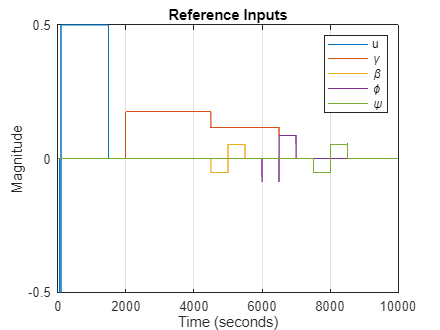

tracked_names = {'u', '\gamma', '\beta', '\phi', '\psi'};
figure(1);
plot(refinputs.Time, refinputs.Data);
xlabel('Time (seconds)');
ylabel('Magnitude');
title('Reference Inputs');
legend(tracked_names, 'location', 'northeast');
grid on;
saveas(gcf, fullfile(figFolder, 'StepInputs.png'));

refM = refinputs.Data;
refM = refM(1:end-1, :);

#### `x States`

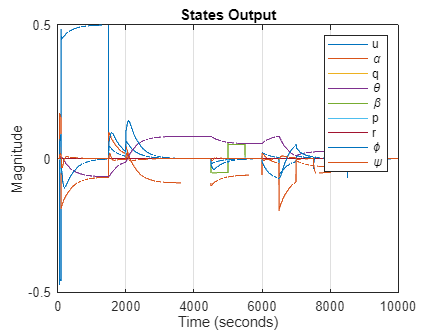

state_names = {'u', '\alpha', 'q', '\theta', '\beta', 'p', 'r', '\phi', '\psi'};
figure(2);
plot(xstate.Time, xstate.Data);
xlabel('Time (seconds)');
ylabel('Magnitude');
title('States Output');
legend(state_names, 'location', 'northeast');
grid on;
saveas(gcf, fullfile(figFolder, 'StatesOut.png'));

xstateM = xstate.Data;
xstateM = xstateM(1:end-1, :);

#### `Control Deflection Outputs`

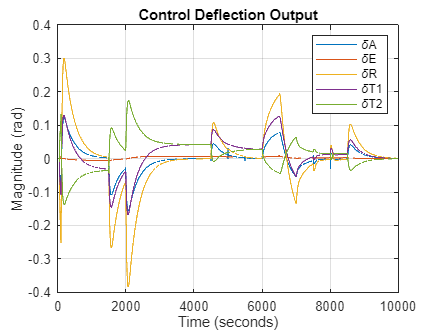

control_names = {'\deltaA', '\deltaE', '\deltaR', '\deltaT1', '\deltaT2'};
figure(3);
plot(controlout.Time, controlout.Data);
xlabel('Time (seconds)');
ylabel('Magnitude (rad)');
title('Control Deflection Output');
legend(control_names, 'location', 'northeast');
grid on;
saveas(gcf, fullfile(figFolder, 'ControlOut.png'));

controlM = controlout.Data;
controlM = controlM(1:end-1, :);

#### `Tracked States `

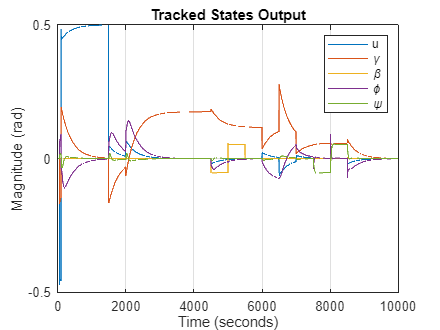

figure(4);
plot(trackedstate.Time, trackedstate.Data);
xlabel('Time (seconds)');
ylabel('Magnitude (rad)');
title('Tracked States Output');
legend(tracked_names, 'location', 'northeast');
grid on;
saveas(gcf, fullfile(figFolder, 'TrackedStates.png'));

trackedM = trackedstate.Data;
trackedM = trackedM(1:end-1, :);

#### `Error dot`

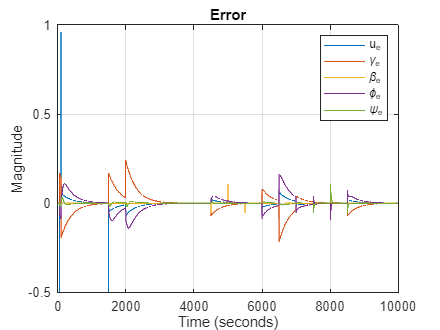

edot_names = {'u_e', '\gamma_e', '\beta_e', '\phi_e', '\psi_e'};
figure(5);
plot(edot.Time, edot.Data);
xlabel('Time (seconds)');
ylabel('Magnitude');
title('Error');
legend(edot_names, 'location', 'northeast');
grid on;
saveas(gcf, fullfile(figFolder, 'edot.png'));

edotM = edot.Data;
edotM = edotM(1:end-1, :);

# `Training Data`

#### `Predictors & Targets`

preds = [xstateM edotM];
targs = controlM;

timeVector = (0:numsamples-1) * sampletime;
timeVector = timeVector(:);

% Create timeseries for predictors and targets
tspreds = timeseries(preds', timeVector(:)); % Use `t(:)` for column vector
tspreds.Name = 'Predictors';
tspreds.TimeInfo.Units = 'seconds';

tstargs = timeseries(targs', timeVector(:)); % Use `t(:)` for column vector
tstargs.Name = 'Targets';
tstargs.TimeInfo.Units = 'seconds';

# `Trimmed Values & Initial Condition`

xtrim = [231.557711564030;
        -0.0592296517743395;
        1.16328047902770e-22;
        -0.0592296517743393;
        0.0175;
        -4.73553938832452e-22;
        -1.85803010324468e-23;
        0.0310395565564283;
        4.13223095338111e-13];

utrim = [-0.030297265012908;
        -0.109967569297416;
        0.037383774558416;
        0.112150991441631;
        0.112151669425404];

IC = [231.557711564030;
      4.05979277400651;
     -13.7311433559468;
     -4.73553938832452e-22;
      1.16328047902770e-22;
     -1.85803010324468e-23;
     0.0310395565564283;
     -0.0592296517743393;
     4.13223095338111e-13];